A = imread('A.png');
B = imread('B.png');
offset = 60;%mm

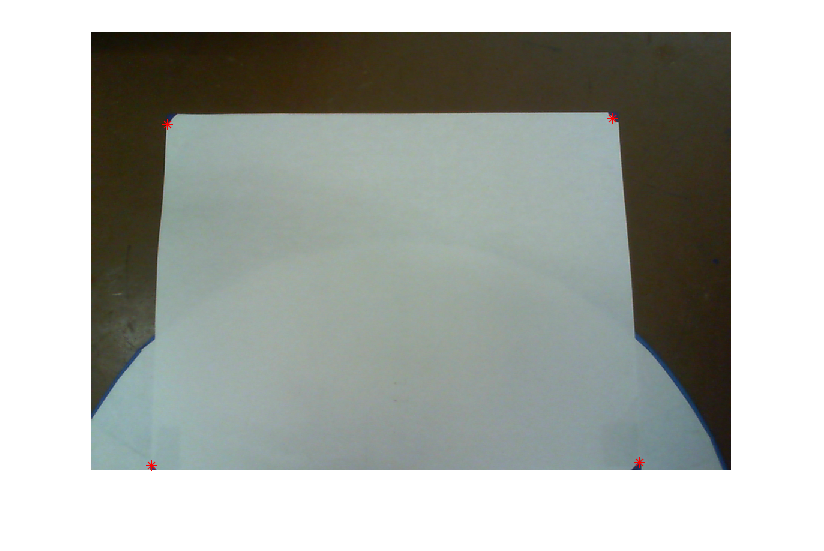

[corners, A] = locationInit();
%[loc,corloc, pivot, centroid] = location(corners, offset, A);
imshow(A);
hold on
plot(corners(:,1),corners(:,2),'r*');

% plot(centroid(:,1),centroid(:,2),'b*');
% plot(pivot(:,1),pivot(:,2),'g*');


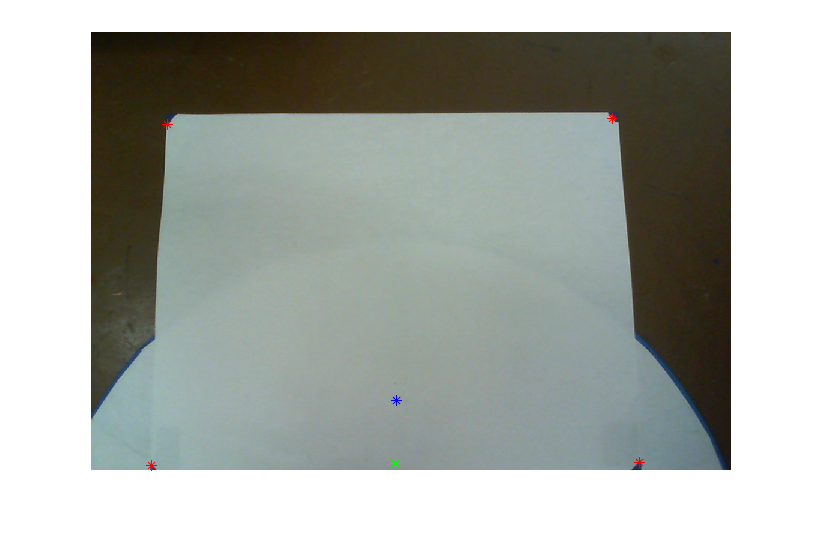

[loc,corloc, pivot, centroid] = location(corners, offset, A);
plot(centroid(:,1),centroid(:,2),'b*');
plot(pivot(:,1),pivot(:,2),'g*');
hold off

% ax = zeros(size(A(:,:,1)));
% ax = insertShape(ax,'Line',[corners(1,:), corners(2,:)]);
% ay = zeros(size(A(:,:,1)));
% ay = insertShape(ay,'Line',[corners(1,:), corners(3,:)]);
% ax = imbinarize(rgb2gray(ax));
% ay = imbinarize(rgb2gray(ay));

% Dx = bwdist(ax);
% Dy = bwdist(ay);
% % RGBx = repmat(rescale(Dx), [1 1 3]);
% % RGBy = repmat(rescale(Dy), [1 1 3]);
% hold on
% imcontour(Dx);
% imcontour(Dy);
% plot(centroid(:,1),centroid(:,2),'b*');
% Dx(round(centroid(:,1)),round(centroid(:,2)));
% Dy(round(centroid(:,1)),round(centroid(:,2)));
mag = getRealDist(corners, [pivot; centroid]);
   c = sqrt(mag^2 + offset^2 - 2*mag*offset*cos(loc(2)+pi/2));
    gamma = pi/2-asin(mag*sin(loc(2)+pi/2)/c);